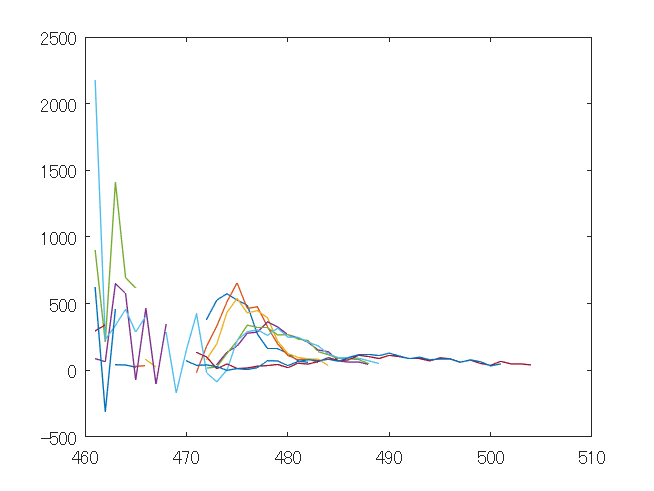

clearvars 
%X点での異常抵抗（test）
%%ファイルへのパスを作る
%それぞれのPCから共有フォルダまでのパスはそれぞれ異なるので各自で設定
pathname.ts3u=getenv('ts3u_path');%old-koalaのts-3uまでのパス
pathname.fourier=getenv('fourier_path');%md0までのpath
pathname.NIFS=getenv('NIFS_path');%resultsまでのpath
pathname.save='C:\Users\kuru1\OneDrive - g.ecc.u-tokyo.ac.jp\過去データ解析\220726';

DOCID='1wG5fBaiQ7-jOzOI-2pkPAeV6SDiHc_LrOdcbWlvhHBw';
T=getTS6log(DOCID);% ログのテーブルを取得

start=460;
frame=50;
elapsedtime=1:frame;
trange=[1:frame+1]+start;

IDXlist=[2911:2913 2925 2926 2927 2931 2933];
tstartlist=[472 472 472 477 477 477 482 482];
tendlist=[482 482 482 487 487 487 500 500];

xJt=zeros(frame,numel(IDXlist));
xEt=zeros(frame,numel(IDXlist));
xeta=zeros(frame,numel(IDXlist));

for i=1:numel(IDXlist)
    IDX=IDXlist(i);
    tstart=tstartlist(i);
    tend=tendlist(i);
    [xJt(:,i), xEt(:,i), xeta(:,i)]=cal_eta(T, IDX, pathname, trange,start,frame);
end

range=[1:frame]+start;
figure
i=1:8;
plot(range,xEt(:,i))

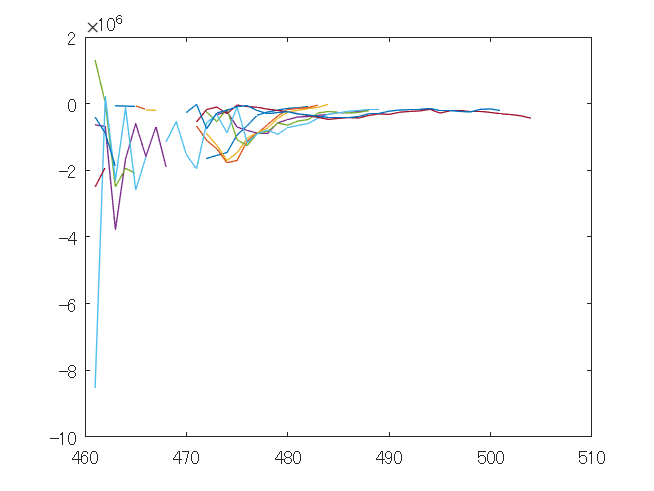


figure
i=1:8;
plot(range,xJt(:,i))

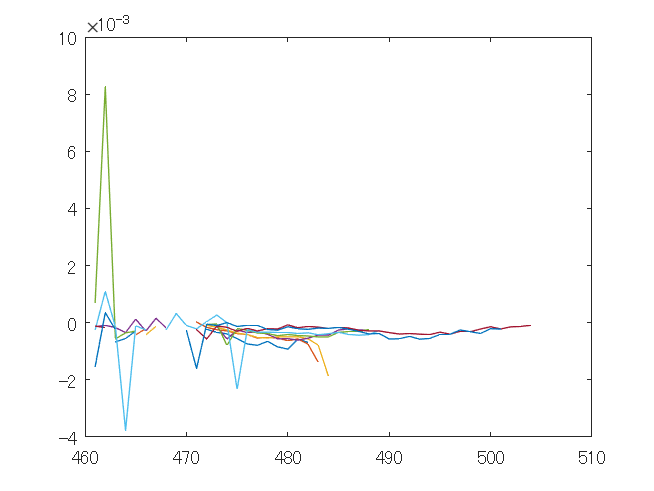


figure
i=1:8;
plot(range,xeta(:,i))

function [date, shot, TF_shot, offset_TF, i_EF, start, v_TF, d_tacq, d_tacqTF, n] = getinput(T,IDX)
date=T.date(IDX);
shot=T.shot(IDX);
TF_shot=T.TFoffset(IDX);
offset_TF=isfinite(TF_shot);

if isnan(T.EF_A_(IDX))%%NaNでないことを確認（ログが空白だとNaNになる）
    i_EF=150;
else  %NaNなら150をとりあえず代入、記入されているときはその値を使う
    i_EF=T.EF_A_(IDX);
end

start=T.Period_StartTime_(IDX);
v_TF=T.TF_kV_(IDX); %TF[kV]

d_tacq=T.d_tacq(IDX);
d_tacqTF=T.TFdtacq(IDX);

n=50; %rz方向のメッシュ数
end

function [xJt,xEt,xeta]=cal_eta(T, IDX, pathname, trange,start,frame)
% trange = tstart:tend+1;
% tsize = tend-tstart+1;

% row = 2;
% column =ceil(tsize/row);

[date, ~, ~, ~, i_EF, ~, ~, d_tacq, d_tacqTF, n] = getinput(T,IDX);%Tのテーブルから入力のリストを出力
[grid2D, data2D] = pcbdata(date, d_tacq, d_tacqTF, trange, [], n,i_EF);

if isstruct(grid2D)==0 %もしdtacqデータがない場合次のloopへ(データがない場合NaNを返しているため)
    return
end

%%%midplaneとかO点、X点を探す
[psimid,mid]=min(data2D.psi,[],2);
[opoint,~]=islocalmin(psimid,1);
[xpoint,~]=islocalmax(psimid,1);
% [xp_psi,maxxp]=max(squeeze(psimid),[],1);
r_index=1:n;

%X点でのJt,Et,eta
xJt=zeros(frame,1);
xEt=zeros(frame,1);

for i=1:frame
    if sum(xpoint(:,:,i))>0   
        r_xind=r_index(xpoint(:,:,i));
        z_xind=mid(xpoint(:,:,i),:,i);
        if numel(r_xind)>1
            [~,I]=max(psimid(r_xind));
            r_xind=r_xind(I);
            z_xind=z_xind(I);
        end
        xJt(i,1)=data2D.Jt(r_xind,z_xind,i);
        xEt(i,1)=data2D.Et(r_xind,z_xind,i);

        
%         r_s=max(2,r_xind-5);
%         r_n=min(n,r_xind+5);

        if z_xind==1 || z_xind==n
            xJt(i,1)=NaN;
            xEt(i,1)=NaN;
        end
    else
        xJt(i,1)=NaN;
        xEt(i,1)=NaN;
    end   
end

xeta=xEt./xJt;

end